close all
clear

q = 5; % quantization level
eps = 2; % privacy parameter
r=0.5; % geometric series constant
axRatio = 3; %the ratio amax/xmax

xmax = 1;
xmax = floor(xmax*q)/q; % We need to make sure they are integers
M = 2*xmax*q+1; % total amount of x samples
x_grid = linspace(-xmax,xmax,M);

% We assign a distribution to X\in x_grid

% x_P = ones(1,M)/M; % Uniform distribution

% x_P = x_grid.^2;
% x_P = x_P./ sum(x_P);

x_P = x_grid-min(x_grid);
x_P = x_P./sum(x_P);

% figure
% plot(x_grid,x_P,'o',LineWidth=1.5);
% xlabel("x",FontSize=13);
% ylabel("P(x)",FontSize=13);
% grid on

% [totalVariance,pMatrix] = opt_variance(eps,r,axRatio,x_grid,x_P);

% For testing, we sample a sequence of epsilon values
eps_grid = linspace(1,8,20);

% The variance of optimal mechanism
VarOpt = zeros(1,length(eps_grid));
for i = 1:length(eps_grid)
    [totalVariance,pMatrix] = opt_variance(eps_grid(i),r,axRatio,x_grid,x_P);
    VarOpt(i) = totalVariance;
end

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.



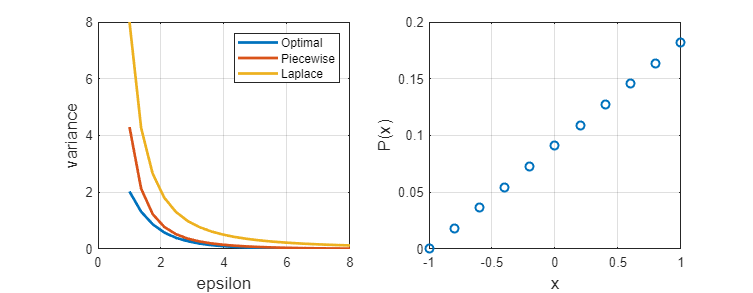

% The variance vector of piece-wise mechanism
VarPiecewise = zeros(1,length(eps_grid));
var_piecewise = @(ti,eps) ti.^2./(exp(eps/2)-1) + (exp(eps/2)+3)/3/(exp(eps/2)-1)^2;
for i = 1:length(eps_grid)
    VarPiecewise(i) = var_piecewise(x_grid,eps_grid(i))*x_P';
end

% The variance vector of Laplace mechanism
VarLaplace = zeros(1,length(eps_grid));
var_laplace = @(ti,eps) ti.^2./(exp(eps/2)-1) + (exp(eps/2)+3)/3/(exp(eps/2)-1)^2;
for i = 1:length(eps_grid)
    VarLaplace(i) = 8/(eps_grid(i))^2;
end



% The plots
figure
cgf = figure;
set(gcf,'position',[0,0,900,350])

subplot(1,2,1)
plot(eps_grid,VarOpt,LineWidth=2);
hold on
plot(eps_grid,VarPiecewise,LineWidth=2);
hold on
plot(eps_grid,VarLaplace,LineWidth=2);
xlabel("epsilon",FontSize=13)
ylabel("variance",FontSize=13)
legend("Optimal", "Piecewise","Laplace")
grid on

subplot(1,2,2)
plot(x_grid,x_P,'o',LineWidth=1.5);
xlabel("x",FontSize=13);
ylabel("P(x)",FontSize=13);
grid on